# Wave-Driven Desalination

Note: this example requires a properly set-up [WEC-Sim install](https://wec-sim.github.io/WEC-Sim/dev/user/getting_started.html) to work properly.

An excellent use case for this toolbox is in wave-driven desalination systems. These systems utilize mechanical energy captured in the motion of a Wave Energy Converter (WEC) to drive some sort of pump, directly pressurizing sea water to the pressures necessary for Sea Water Reverse Osmosis (SWRO), see [OsmoticPressure.m](matlab:open('..\..\OsmoticPressure.m')) example for more on SWRO. An example concept drawing of this system is shown below: 

In motion, this looks like:

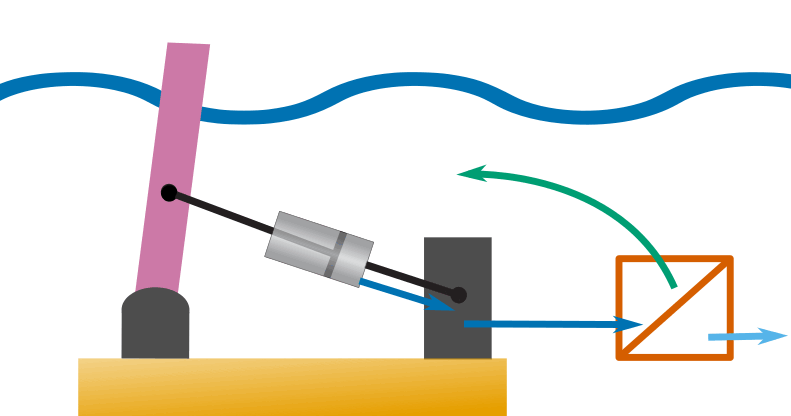

Now this is a significant simplification, in reality, we'd use a double acting piston to take advantage of the motion in both directions as well as an accumulator to smooth the feed flow, but this shows the basic idea. However, even with the accumulator, this system clearly does not run the SWRO membranes at steady state, and due to the high coupling between the WEC and SWRO systems, a fully coupled model that connects these two systems and simulates unsteady SWRO processes is required. This makes Simscape an excellent option, but only with this new toolbox.

## Basic SWRO Desalination Hydraulic Model

Before we involve WEC-Sim, lets first discuss the basic SWRO hydraulic model.

Take a minute to explore the [BasicDesalHydraulics.slx](matlab:open('.\BasicDesalHydraulics.slx')) model. There are a few main elements, first the hydraulic cylinder, which also contains directional valves to ensure water is taken in from the sea water source and sent out into the hydraulic circuit. You can see two versions of the hydraulic cylinder model. One with check valves, representing a more realistic depiction, and one with controlled area restrictions, with the area controlled by the sign of the velocity signal. These valves mimic the behavior of the check valves, but make things easier on the solver. There is also a gas charged accumulator which smooths the flow, a pressure relief valve to make sure the maximum pressure in the SWRO membrane is not exceeded, the membrane model itself, and finally a resistance on the brine flow which can be tuned to set the recovery ratio. This basic test model just represents the WEC motion with a sine wave, try out adjusting parameters to change the behavior of the flow rates, pressure, and concentratrations.

load_system("tBasicDesalHydraulics.slx");
set_param('tBasicDesalHydraulics/Desal Hydraulic Model/Linear Resistance (SS)','R','65e6');
save_system("tBasicDesalHydraulics.slx",'SaveDirtyReferencedModels','on');
close_system('tBasicDesalHydraulics.slx')
out1=sim("tBasicDesalHydraulics.slx");
t_v = out1.simout.Velocity.Time;
v_in =  out1.simout.Velocity.Data;
t = out1.simout.In_Flow.Time;
Q_in =  out1.simout.In_Flow.Data;
Q_perm = out1.simout.Perm_Flow.Data;
Q_brine = out1.simout.Brine_Flow.Data;
Q_PRV = out1.simout.PRV_Flow.Data;

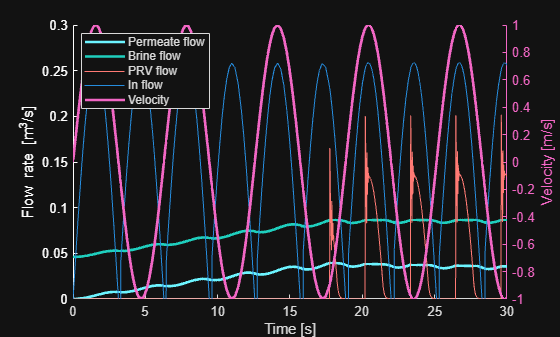

c = load_colors();
figure('Name','Isolated PTO Flows')
colororder([1 1 1;c.vel])
yyaxis left
line(t,Q_perm,'DisplayName','Permeate flow','Color',c.perm,'linewidth',2)
line(t,Q_brine,'DisplayName','Brine flow','color',c.brine,'LineWidth',2,'LineStyle','-')
line(t,Q_PRV,'DisplayName','PRV flow','LineStyle','-','Color',c.prv)
line(t,Q_in,'DisplayName','In flow','LineStyle','-','color',c.in)

ylabel('Flow rate [m^3/s]')
ylim([0,0.3])
yyaxis right
line(t_v,v_in,'DisplayName','Velocity','LineWidth',2)
ylabel('Velocity [m/s]')
xlabel('Time [s]')
legend('location','best')

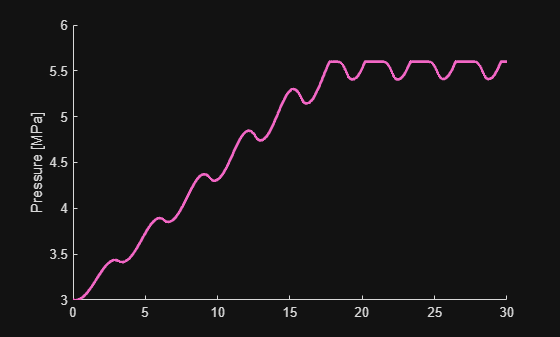

figure('Name','Isolated PTO Pressure')
line(t,out1.simout.Feed_Pressure.Data/1e6,'Color',c.vel,'LineWidth',2)
ylabel('Pressure [MPa]')

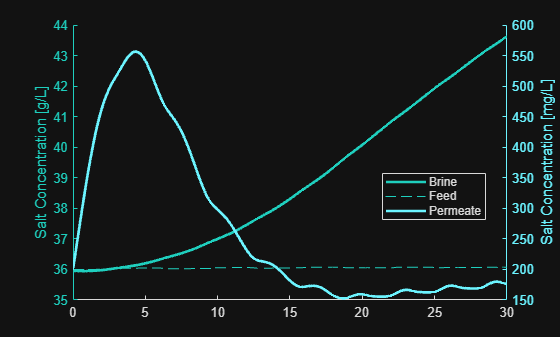

figure('Name','Isolated PTO Concentrations')
colororder([c.brine;c.perm])
yyaxis left
line(t,out1.simout.Brine_Concentration.Data,'DisplayName','Brine','linewidth',2)
line(t,out1.simout.Feed_Concentration.Data,'DisplayName','Feed')
ylabel('Salt Concentration [g/L]')
yyaxis right
line(t,out1.simout.Perm_Concentration.Data*1e3,'DisplayName','Permeate','linewidth',2)
ylabel('Salt Concentration [mg/L]')
legend('Location','best')

## Integration with WEC-Sim

While this dynamic simulation of SWRO is important, to truly understand the performance of a wave-driven desalination system we need to couple the simulation of the WEC dynamics and SWRO together. Convieniently WEC-Sim is built in Simulink, making it easy to connect a WEC model to a power take-off model built in Simscape. You'll need to give it some time to run though.

load_system('waveDrivenDesal.slx');
set_param('waveDrivenDesal/SWRO PTO', 'Commented', 'off');
set_param('waveDrivenDesal/SWRO PTO w// ERU', 'Commented', 'on');
set_param('waveDrivenDesal/SWRO PTO/Linear Resistance (SS)','R','65e6');
save_system('waveDrivenDesal', 'SaveDirtyReferencedModels','on')
close_system('waveDrivenDesal')
wecSim

WEC-Sim: An open-source code for simulating wave energy converters
Version: 7.0.0

Initializing the Simulation Class...
	Case Dir: C:\Users\ndegoede\Projects\simscape_desal_internal 

WEC-Sim Pre-processing ...   
Elapsed time is 1.026379 seconds.

WEC-Sim Simulation Settings:
	Start Time                     (sec) = 0
	End Time                       (sec) = 300
	Time Step Size                 (sec) = 0.1
	Ramp Function Time             (sec) = 0
	Convolution Integral Interval  (sec) = 10
	 Number of Time Steps     = 3000 

Wave Environment: 
	Wave Type                            = Irregular Waves (Predefined Random Phase)
	Spectrum Type                        = Pierson-Moskowitz  
	Significant Wave Height, Hs      (m) = 9.86
	Peak Wave Period, Tp           (sec) = 2.64

List of Body:
 
Number of Hydro Bodies = 2 

	***** Body Number 1, Name: flap *****
	Body CG                          (m) = [0,0,-3.9]
	Body Mass                       (kg) = 127000 
	Body Moments of Inertia       (kgm2

Elapsed time is 840.507504 seconds.

Post-processing and saving...   
Elapsed time is 0.250897 seconds.


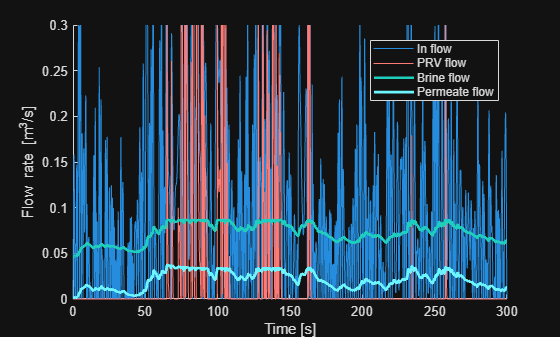

t_v = simout.Velocity.Time;
v_in =  simout.Velocity.Data;
t = simout.In_Flow.Time;
Q_in = simout.In_Flow.Data;
Q_perm = simout.Perm_Flow.Data;
Q_brine = simout.Brine_Flow.Data;
Q_PRV = simout.PRV_Flow.Data;
figure('Name','Flows')
%yyaxis right
%line(t_v,v_in,'DisplayName','Velocity')
%ylabel('Velocity [m/s]')
%yyaxis left
line(t,Q_in,'DisplayName','In flow','color',c.in)
line(t,Q_PRV,'DisplayName','PRV flow','color',c.prv)
line(t,Q_brine,'DisplayName','Brine flow','color',c.brine,'LineWidth',2)
line(t,Q_perm,'DisplayName','Permeate flow','color',c.perm,'LineWidth',2)
ylabel('Flow rate [m^3/s]')
ylim([0,0.3])
%xlim([200,250])
xlabel('Time [s]')
legend('location','best')

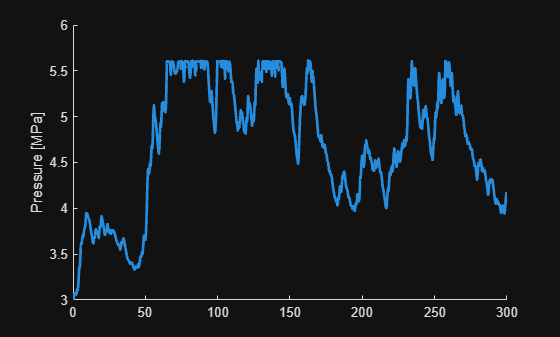

figure('Name','Pressure')
line(t,simout.Feed_Pressure.Data/1e6,'Color',c.in,'LineWidth',2)
%xlim([200,250])
ylabel('Pressure [MPa]')

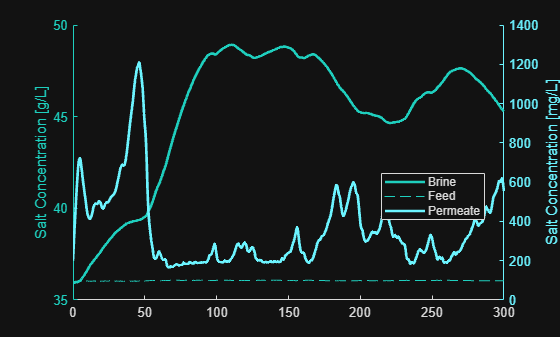

figure('Name','Concentrations');
colororder([c.brine;c.perm])
yyaxis left
line(t,simout.Brine_Concentration.Data,'DisplayName','Brine','LineWidth',2)
line(t,simout.Feed_Concentration.Data,'DisplayName','Feed')
ylabel('Salt Concentration [g/L]')
yyaxis right
line(t,simout.Perm_Concentration.Data*1e3,'DisplayName','Permeate','LineWidth',2)
ylabel('Salt Concentration [mg/L]')
%xlim([200,250])
legend('Location','best')

## Improving the Design

In our wave-driven desalination system, we have 3 main final energy states: directly used in desalination, brine waste, and excess that leaves the pressure relief valve. Let's plot the breakdown to see how muich of the energy entering the system actually ends up direcetly used in desalination.

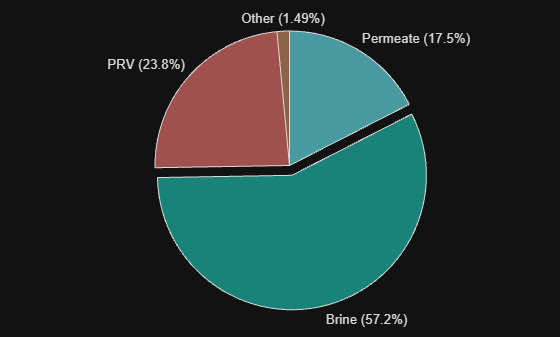

t = simout.In_Flow.Time;
E_in = trapz(t,simout.In_Flow.Data.*simout.Feed_Pressure.Data);
E_prv = trapz(t,simout.PRV_Flow.Data.*simout.Feed_Pressure.Data);
E_brine = trapz(t,simout.Brine_Flow.Data.*simout.Brine_Pressure.Data);
E_perm = trapz(t,simout.Perm_Flow.Data.*simout.Feed_Pressure.Data);
E_other = max([E_in - E_prv - E_brine - E_perm,0]);
figure('Name','basic energy')
energy = [E_perm,E_brine,E_prv,E_other];
energy_initial = energy;
labels = {'Permeate','Brine','PRV','Other'};
p = piechart(energy,labels,ExplodedWedges=2);
p.ColorOrder = [c.perm;c.brine;c.prv;c.other];

The Brine flow contains a massive amount of energy, therefore, one might think we could improve this system by increasing the resistance on the brine. That would raise the pressure in the system (more permeate) and lead to less high pressure water being wasted out the brine stream. Let's see how well this works.

## Increased Brine Resistance

load_system('waveDrivenDesal.slx');
set_param('waveDrivenDesal/SWRO PTO', 'Commented', 'off');
set_param('waveDrivenDesal/SWRO PTO w// ERU', 'Commented', 'on');
set_param('waveDrivenDesal/SWRO PTO/Linear Resistance (SS)','R','195e6'); % 3x resistance for brine flow
save_system('waveDrivenDesal', 'SaveDirtyReferencedModels','on')
close_system('waveDrivenDesal')
wecSim

WEC-Sim: An open-source code for simulating wave energy converters
Version: 7.0.0

Initializing the Simulation Class...
	Case Dir: C:\Users\ndegoede\Projects\simscape_desal_internal 

WEC-Sim Pre-processing ...   
Elapsed time is 0.849246 seconds.

WEC-Sim Simulation Settings:
	Start Time                     (sec) = 0
	End Time                       (sec) = 300
	Time Step Size                 (sec) = 0.1
	Ramp Function Time             (sec) = 0
	Convolution Integral Interval  (sec) = 10
	 Number of Time Steps     = 3000 

Wave Environment: 
	Wave Type                            = Irregular Waves (Predefined Random Phase)
	Spectrum Type                        = Pierson-Moskowitz  
	Significant Wave Height, Hs      (m) = 9.86
	Peak Wave Period, Tp           (sec) = 2.64

List of Body:
 
Number of Hydro Bodies = 2 

	***** Body Number 1, Name: flap *****
	Body CG                          (m) = [0,0,-3.9]
	Body Mass                       (kg) = 127000 
	Body Moments of Inertia       (kgm2

Elapsed time is 811.867128 seconds.

Post-processing and saving...   
Elapsed time is 0.158416 seconds.


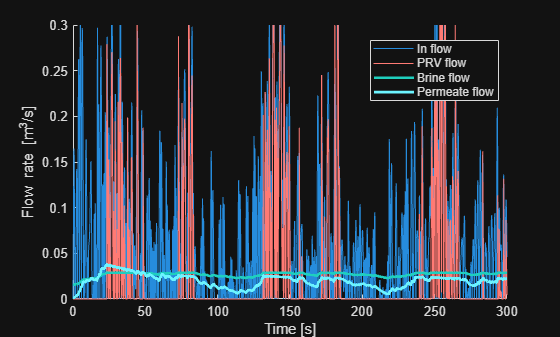

t_v = simout.Velocity.Time;
v_in =  simout.Velocity.Data;
t = simout.In_Flow.Time;
Q_in = simout.In_Flow.Data;
Q_perm = simout.Perm_Flow.Data;
Q_brine = simout.Brine_Flow.Data;
Q_PRV = simout.PRV_Flow.Data;
figure('Name','Flows')
%yyaxis right
%line(t_v,v_in,'DisplayName','Velocity')
%ylabel('Velocity [m/s]')
%yyaxis left
line(t,Q_in,'DisplayName','In flow','color',c.in)
line(t,Q_PRV,'DisplayName','PRV flow','color',c.prv)
line(t,Q_brine,'DisplayName','Brine flow','color',c.brine,'LineWidth',2)
line(t,Q_perm,'DisplayName','Permeate flow','color',c.perm,'LineWidth',2)
ylabel('Flow rate [m^3/s]')
ylim([0,0.3])
%xlim([200,250])
xlabel('Time [s]')
legend('location','best')

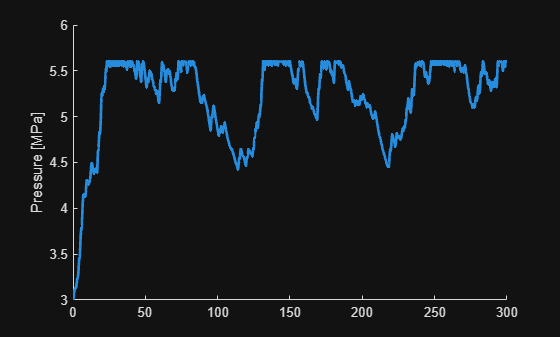

figure('Name','Pressure')
line(t,simout.Feed_Pressure.Data/1e6,'Color',c.in,'LineWidth',2)
%xlim([200,250])
ylabel('Pressure [MPa]')

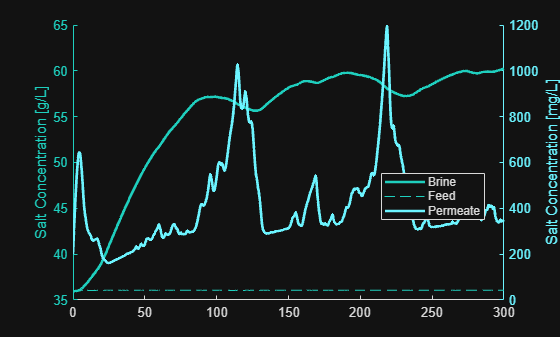

figure('Name','Concentrations');
colororder([c.brine;c.perm])
yyaxis left
line(t,simout.Brine_Concentration.Data,'DisplayName','Brine','LineWidth',2)
line(t,simout.Feed_Concentration.Data,'DisplayName','Feed')
ylabel('Salt Concentration [g/L]')
yyaxis right
line(t,simout.Perm_Concentration.Data*1e3,'DisplayName','Permeate','LineWidth',2)
ylabel('Salt Concentration [mg/L]')
%xlim([200,250])
legend('Location','best')

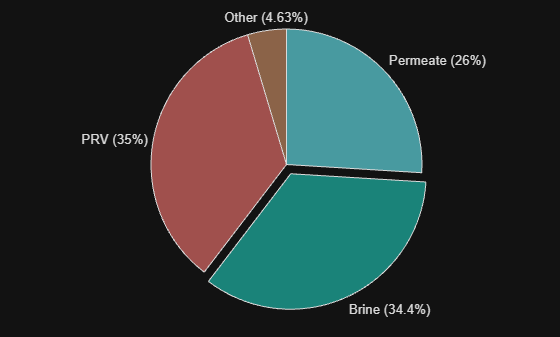

t = simout.In_Flow.Time;
E_in = trapz(t,simout.In_Flow.Data.*simout.Feed_Pressure.Data);
E_prv = trapz(t,simout.PRV_Flow.Data.*simout.Feed_Pressure.Data);
E_brine = trapz(t,simout.Brine_Flow.Data.*simout.Brine_Pressure.Data);
E_perm = trapz(t,simout.Perm_Flow.Data.*simout.Feed_Pressure.Data);
E_other = max([E_in - E_prv - E_brine - E_perm,0]);
figure('Name','basic energy')
energy = [E_perm,E_brine,E_prv,E_other];
energy_brine_resist = energy;
labels = {'Permeate','Brine','PRV','Other'};
p = piechart(energy,labels,ExplodedWedges=2);
p.ColorOrder = [c.perm;c.brine;c.prv;c.other];

While it did cut down on the brine flow considerably, it didn't increase the peremate production all that much, instead it increased the PRV flow a lot more. The reason for this is that the brine stream does more than just "waste energy" it also serves an important role in flushing salt out of the membrane feed chamber. We can see this in the concetration plots, the brine concentration is much higher in this system, meaning the osmotic pressure accross the membrane is also much higher. For this reason the brine flow isn't just redireceted into the permeate flow and is instead split between the PRV and permeate with the larger piece leaving out the PRV. Additionally that high concentration in the feed chamber leads to higher salt concentration in the feed, and in any desalination system there should be a required maximum salinity of the permeate that this could be violating. 

While this strategy didn't work so well, there are other options we could try out using this domain. Many SWRO desalination plants utilize energy recovery units (ERUs) to help with this problem. ERUs take energy from the brine flow and use it to pressurize more feed flow increasing overall efficiency. Let's switch to the ERU PTO in the waveDrivenDesal model.

## ERU

load_system('waveDrivenDesal.slx');
set_param('waveDrivenDesal/SWRO PTO', 'Commented', 'on');
set_param('waveDrivenDesal/SWRO PTO w// ERU', 'Commented', 'off');
close_system('waveDrivenDesal.slx',1)
wecSim

WEC-Sim: An open-source code for simulating wave energy converters
Version: 7.0.0

Initializing the Simulation Class...
	Case Dir: C:\Users\ndegoede\Projects\simscape_desal_internal 

WEC-Sim Pre-processing ...   
Elapsed time is 1.090324 seconds.

WEC-Sim Simulation Settings:
	Start Time                     (sec) = 0
	End Time                       (sec) = 300
	Time Step Size                 (sec) = 0.1
	Ramp Function Time             (sec) = 0
	Convolution Integral Interval  (sec) = 10
	 Number of Time Steps     = 3000 

Wave Environment: 
	Wave Type                            = Irregular Waves (Predefined Random Phase)
	Spectrum Type                        = Pierson-Moskowitz  
	Significant Wave Height, Hs      (m) = 9.86
	Peak Wave Period, Tp           (sec) = 2.64

List of Body:
 
Number of Hydro Bodies = 2 

	***** Body Number 1, Name: flap *****
	Body CG                          (m) = [0,0,-3.9]
	Body Mass                       (kg) = 127000 
	Body Moments of Inertia       (kgm2

Elapsed time is 1242.606788 seconds.

Post-processing and saving...   
Elapsed time is 0.145254 seconds.


## ERU Results

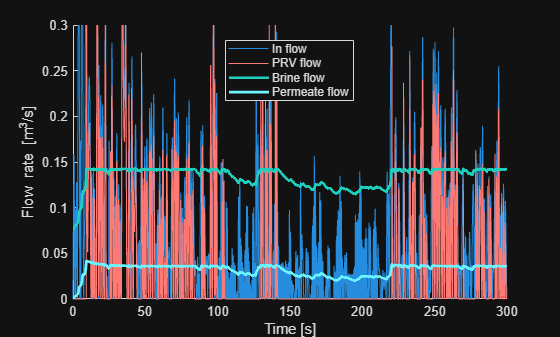

t_v = simout1.Velocity.Time;
v_in =  simout1.Velocity.Data;
t = simout1.In_Flow.Time;
Q_in = simout1.In_Flow.Data;
Q_perm = simout1.Perm_Flow.Data;
Q_brine = simout1.Brine_Flow.Data;
Q_PRV = simout1.PRV_Flow.Data;
figure('Name','Flows')
%yyaxis right
%line(t_v,v_in,'DisplayName','Velocity')
%ylabel('Velocity [m/s]')
%yyaxis left
line(t,Q_in,'DisplayName','In flow','color',c.in)
line(t,Q_PRV,'DisplayName','PRV flow','color',c.prv)
line(t,Q_brine,'DisplayName','Brine flow','color',c.brine,'linewidth',2)
line(t,Q_perm,'DisplayName','Permeate flow','color',c.perm,'linewidth',2)
ylabel('Flow rate [m^3/s]')
ylim([0,0.3])
%xlim([200,250])
xlabel('Time [s]')
legend('location','best')

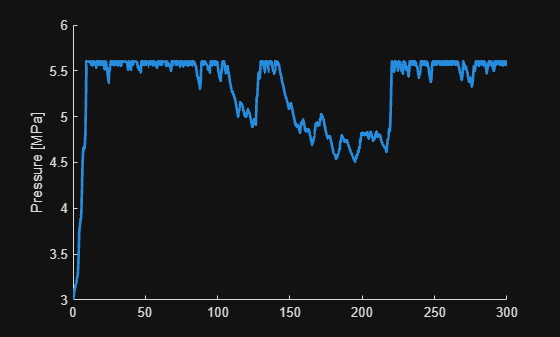

figure('Name','Pressure')
line(t,simout1.Feed_Pressure.Data/1e6,'Color',c.in,'LineWidth',2)
%xlim([200,250])
ylabel('Pressure [MPa]')

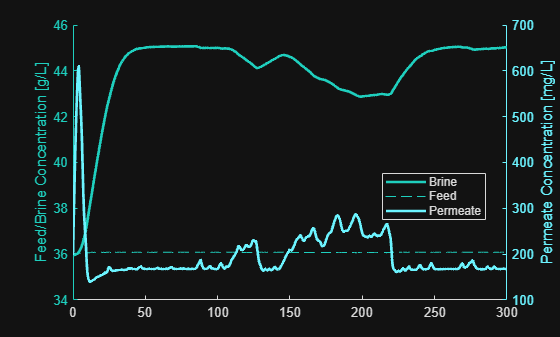

figure('Name','Concentrations')
colororder([c.brine;c.perm])
yyaxis left
line(t,simout1.Brine_Concentration.Data,'DisplayName','Brine','LineWidth',2)
line(t,simout1.Feed_Concentration.Data,'DisplayName','Feed')
ylabel('Feed/Brine Concentration [g/L]')
yyaxis right
line(t,simout1.Perm_Concentration.Data*1e3,'DisplayName','Permeate','LineWidth',2)
ylabel('Permeate Concentration [mg/L]')
%xlim([200,250])
legend('Location','best')

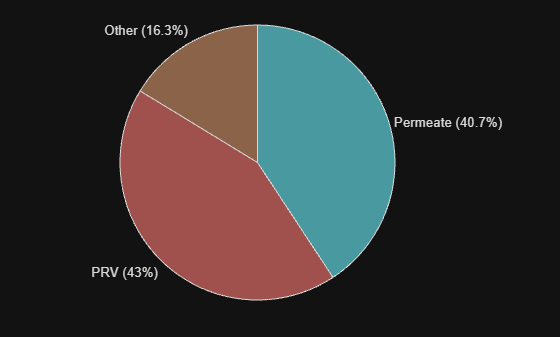

t = simout1.ERU_Flow.Time;
E_in = trapz(t,simout1.In_Flow.Data.*simout1.Feed_Pressure.Data);
E_prv = trapz(t,simout1.PRV_Flow.Data.*simout1.Feed_Pressure.Data);
E_perm = trapz(t,simout1.Perm_Flow.Data.*simout1.Feed_Pressure.Data);
E_other = E_in - E_prv - E_perm;
figure('Name','basic energy')
energy = [E_perm,E_prv,E_other];
energy_eru = energy;
labels = {'Permeate','PRV','Other'};
p = piechart(energy,labels);
p.ColorOrder = [c.perm;c.prv;c.other];

This worked much better, even though the PRV flow is also quite large, the peremate production has seen a massive increase. And in the concentration plot, we can also see that the concentration of the permeate has actually decreased as well. This is because the ERU provides a way to increase pressure in the feed without simultaneously increasing the brine concentration and therefore the osmotic pressure difference. The high amount of flow out the PRV does suggest that we could further improve this desing though either with a larger SWRO system (more membrane area) or a larger hydraulic accumulator. Feel free to try these out on your own. However, before we can truly claim that this more "efficient" PTO design is the best we've investigated so far we need to look at the actual energy values and not just the percentages. Due to the highly coupled nature of this system, there is no guarantee that the energy into each of these systems is the same (in fact, it's guaranteed that it will be different).

## Energy Comparison

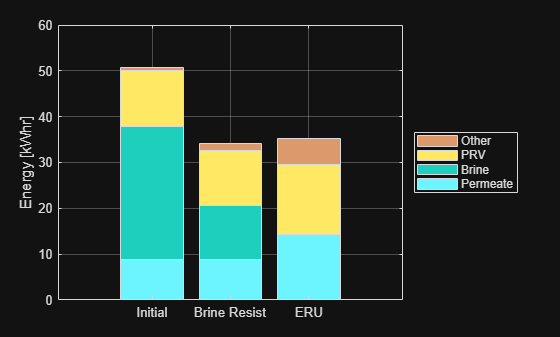

energyPlot = [
    energy_initial(1),      energy_initial(2),      energy_initial(3),      energy_initial(4);
    energy_brine_resist(1), energy_brine_resist(2), energy_brine_resist(3), energy_brine_resist(4);
    energy_eru(1),          0,                      energy_eru(2),          energy_eru(3)
]/(60*60*1e3);
figure
b = bar(energyPlot,'stacked');
b(1).FaceColor = c.perm;
b(2).FaceColor = c.brine;
brine12b(3).FaceColor = c.prv;
b(4).FaceColor = c.other;
xticklabels({'Initial','Brine Resist','ERU'})
ylabel('Energy [kWhr]')
legend({'Permeate','Brine','PRV','Other'}, ...
       'Location','eastoutside')

grid on

This reveals a few interesting trends. First we see that increasing the brine resistance didn't actually increase the permeate flow by as much as the energy pie chart suggested, it just cut down the energy that left out the brine without increasing the energy that went to any other ending state. Additionally, the ERU is not quite as impactful as the pie chart suggested, although it does clearly increase the energy in the permeate, it signifcantly reduced the energy into the system, suggesting the PTO is a poor match for the WEC design. 

function c = load_colors()
    c = struct();
    c.perm  =   [0.4230    0.9560    1.0000];
    c.brine =   [0.1210    0.8110    0.7450];
    c.prv   =   [1.0000    0.4780    0.4540];
    c.in    =   [0.1490    0.5490    0.8660];
    c.other =   [0.8620    0.6000    0.4230];
    c.vel   =   [0.9490    0.4030    0.7720];
end